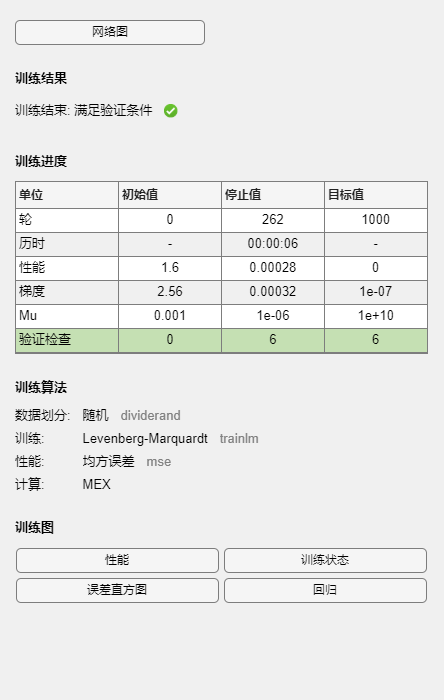

%% DPD Extraction

% EXAMPLE for How to Extract DPD Models in Matlab
%%  Read Input/Output Signal from txt File

clc;clear;

% Read txt file
fileID = fopen('Data\Sys_input_i.txt'); C = textscan(fileID, '%f'); input_i = C{1, 1}; fclose(fileID);
fileID = fopen('Data\Sys_input_q.txt'); C = textscan(fileID, '%f'); input_q = C{1, 1}; fclose(fileID);
fileID = fopen('Data\Sys_output_i.txt');C = textscan(fileID, '%f'); output_i = C{1, 1}; fclose(fileID);
fileID = fopen('Data\Sys_output_q.txt');C = textscan(fileID, '%f'); output_q = C{1, 1}; fclose(fileID);
dim = length(input_i) / 2;
[x_i, x_q, y_i, y_q] = deal(zeros(dim, 1));
for k = 1:dim 
    [x_i(k), x_q(k), y_i(k), y_q(k)] = deal(input_i(2 * k), input_q(2 * k), output_i(2 * k), output_q(2 * k));
end

% Input/Output complex signal
x_sync_01 = x_i + 1j * x_q;
y_sync_01 = y_i + 1j * y_q;

%%  -----------------------------Example I : Feedforward Neural Network----------------------------

% Set Input/Output Matrix
M=2; % Memory Depth
X1 = zeros(2*(M + 1), dim-M);
for j = 1:length(y_i) - M
    X1(:, j) = [y_i(j : j + M); y_q(j : j + M)];
end
Y = [x_i(M + 1 : end)'; x_q(M + 1 : end)'];

% Adjust Parameters and Train Models
net = feedforwardnet(5 ); 
model = train(net, X1, Y);


% Check Modeling Performance and Save Models
Y_pred = sim(model, X1);
a = Y_pred(1, :) + Y_pred(2, :) * 1i;
b = Y(1, :) + Y(2, :) * 1i;
nmse_db = NMSE_dB(a, b)

nmse_db = -31.5451

save('Method\whole_1.mat', 'model');

